# **Steering Linkage Simulation**

This script allows changing of steering linkage parameters and reflects these changes in visuals and plots.

To view everything simultaneously, select 'Hide Code', and zoom out using `ctrl + `[`-`]

%% Base Values %%
clear; format shortG;

% Constants
car = carV4();
wheelbase = car.Wheelbase;
trackwidth = car.Trackwidth;
rack_max_travel = car.RPmaxTravel;
rnp_ratio = car.RPratio;

% Flexible Parameters
setback = 250;          % from SUS geometry: 285.37 plane to wheel
kingpin2contact = 177;  % to centre of contact patch (scrub radius kinda)
connection_length = 350; % distance between tie rod connections on extension rod
steering_arm_Ivec = [15 105];  % x-inset, y-inset (from kingpin)

% *the above simply for a vertical kingpin with no offset

%% Checks and Basic Calculations %%
% Calculated Constants
tie_rod_Ivec(1) = 0.5*(trackwidth - connection_length) - kingpin2contact - steering_arm_Ivec(1);
tie_rod_Ivec(2) = setback - steering_arm_Ivec(2);
tie_rod_length = norm(tie_rod_Ivec);
kingpin_pos = [0.5*trackwidth - kingpin2contact, wheelbase];
kingpin_posL = [-0.5*trackwidth + kingpin2contact, wheelbase];
find_rack_pos = @(dh) rnp_ratio * dh/360;
find_yoke_angle = @(pos) pos/rnp_ratio * 360;

% Verify geometry
if any(tie_rod_Ivec < 0)
    error('Invalid geometry');
end

% Slider ends (steering stops)
RoM = sqrt((tie_rod_length + norm(steering_arm_Ivec))^2 - setback^2) - 0.5*(trackwidth - 2*kingpin2contact - connection_length);  % fully extended
max_movement = floor(min(rack_max_travel, RoM)*1e6)/1e6;
max_movement_neg = -max_movement;
max_yoke = floor(find_yoke_angle(max_movement)*10)/10;
max_yoke_neg = -max_yoke;

yoke_angle = -1 *23.9; % shown sign is flipped
compute_supplementary = true;
force_fit = false;

rack_pos = find_rack_pos(yoke_angle);
rnp_end_pos = [0.5*connection_length + rack_pos, wheelbase - setback];
rnp_end_posL = [-0.5*connection_length + rack_pos, wheelbase - setback];
rnp2kingpin_vec = kingpin_pos - rnp_end_pos;
rnp2kingpin_vecL = kingpin_posL - rnp_end_posL;


%% Generate Diagram %%

[whl_angle, tr_angle, rnp_end_pos] = solve_linkage('right', rack_pos, wheelbase, setback, connection_length, tie_rod_length, steering_arm_Ivec, kingpin_pos);
[whl_angleL, tr_angleL, rnp_end_posL] = solve_linkage('left', rack_pos, wheelbase, setback, connection_length, tie_rod_length, steering_arm_Ivec, kingpin_posL);

whl_angle

whl_angle =       -13.277


whl_angleL

whl_angleL =       -11.225



% Ackerman lines
iczv = @(pos, angle) pos(1) + pos(2).*cotd(angle);

intR = iczv(kingpin_pos, -whl_angle)

intR =         11265


intL = iczv(kingpin_posL, -whl_angleL)

intL =         12391


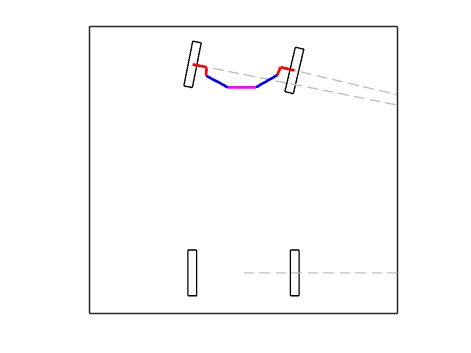


% Diagram
fig = figure(1); clf; hold on;
box on; xticks([]); yticks([]);  % comment out for dimensions
axis equal;

tire([-0.5*trackwidth 0], 0, car);
tire([0.5*trackwidth 0], 0, car);
pos = kingpin_pos + rot([kingpin2contact 0], whl_angle);
tire(pos, whl_angle, car);
pos = kingpin_posL - rot([kingpin2contact 0], whl_angleL);
tire(pos, whl_angleL, car);

if (abs(whl_angle) > 10^-10)
    plot([0, (-sign(whl_angle)*max(abs(intR), abs(intL)))], [0 0], '--', 'color', [.75 .75 .75]);
    plot([intR, kingpin_pos(1)], [0, kingpin_pos(2)], '--', 'color', [.75 .75 .75]);
    plot([intL, kingpin_posL(1)], [0, kingpin_posL(2)], '--', 'color', [.75 .75 .75]);
    fit = xlim;
    if (~force_fit && sum(abs(fit)) > 5*wheelbase)
        xlim([-1.5*trackwidth, 1.5*trackwidth]);
        ylim([-0.2*wheelbase, 1.2*wheelbase]);
    else
        xlim(1.1*fit);
    end
else
    ylim([-0.2*wheelbase, 1.2*wheelbase]);
end

draw({rnp_end_pos, -connection_length}, 'm');
draw({rnp_end_pos, rot([tie_rod_length 0], tr_angle)}, 'b');
draw({kingpin_pos, rot([kingpin2contact 0], whl_angle)}, 'r');
draw({kingpin_pos, rot(-steering_arm_Ivec, whl_angle)}, 'r');
draw({rnp_end_posL, rot([-tie_rod_length 0], -tr_angleL)}, 'b');
draw({kingpin_posL, rot([-kingpin2contact 0], whl_angleL)}, 'r');
draw({kingpin_posL, rot(-[-steering_arm_Ivec(1) steering_arm_Ivec(2)], whl_angleL)}, 'r');


%whl_angle
%whl_angleL
if ~compute_supplementary
    disp('execution halted – plots can be enabled above');
    return;
end

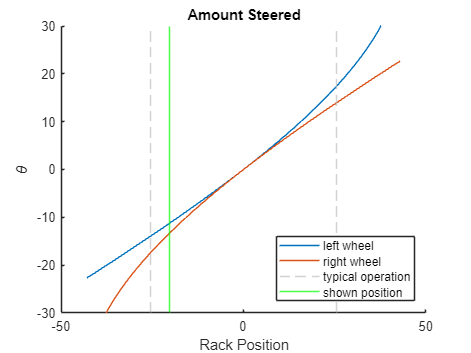

%% Ackerman Closeness %%

test_positions = linspace(max_movement_neg, max_movement, 128);
rightwhl = zeros(length(test_positions), 1);
leftwhl = zeros(length(test_positions), 1);
for i = 1:length(test_positions)
    test_pos = test_positions(i);
    [whl_angle, ~, ~] = solve_linkage('right', test_pos, wheelbase, setback, connection_length, tie_rod_length, steering_arm_Ivec, kingpin_pos);
    [whl_angleL, ~, ~] = solve_linkage('left', test_pos, wheelbase, setback, connection_length, tie_rod_length, steering_arm_Ivec, kingpin_posL);
    rightwhl(i) = whl_angle;
    leftwhl(i) = whl_angleL;
end

% Wheel angle
% add zoom btn %
figure(2); clf; hold on;
title('Amount Steered');

p4 = xline(rack_pos, 'g');
target_radius = 12000; % 12m corner radius, tightest we expect to take at speed
expected_slip = 3;     % use mv^2/r and the contact.m plot
target_steered = acotd((target_radius-0.5*trackwidth)/wheelbase) + expected_slip;
typical = interp1(0.5*(leftwhl+rightwhl), test_positions, target_steered);
p3 = xline(-typical, '--', 'color', [.75 .75 .75]); xline(typical, '--', 'color', [.75 .75 .75]);

p1 = plot(test_positions, leftwhl);
p2 = plot(test_positions, rightwhl);

xlabel('Rack Position'); ylabel('\theta');
legend([p1 p2 p3 p4], {'left wheel', 'right wheel', 'typical operation', 'shown position'}, 'Location', 'southeast');

zoomlimitsX = xlim;
xlim(zoomlimitsX);
ylim([-30 30])

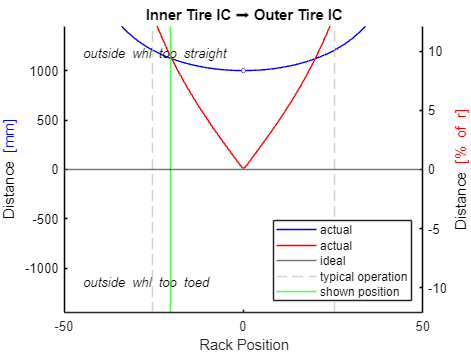


% Instant centres
figure(3); clf; hold on;
title('Inner Tire IC ➡ Outer Tire IC');

xlabel('Rack Position');
rightICZV = iczv(kingpin_pos, -rightwhl);
leftICZV = iczv(kingpin_posL, -leftwhl);

xlim(zoomlimitsX);
q5 = xline(rack_pos, 'g');
q4 = xline(-typical, '--', 'color', [.75 .75 .75]); xline(typical, '--', 'color', [.75 .75 .75]);
q3 = yline(0, '-k', 'color', [.25 .25 .25]);

% zoom curves to distinguish
boundPlotD = 1.2 * max(interp1(test_positions, leftICZV-rightICZV, typical), abs(min(leftICZV-rightICZV))); % assumes a U-shape
boundPlotPct = 100*boundPlotD/target_radius;

yyaxis right;
q2 = plot(test_positions, 100*(leftICZV-rightICZV)./(0.5*abs(leftICZV+rightICZV)), 'r');
ylim([-boundPlotPct boundPlotPct]);
ylabel('Distance \color{red}[% of r]', 'interpreter', 'tex');
set(gca,'YColor','k');

yyaxis left;
q1 = plot(test_positions, leftICZV-rightICZV, 'b');
plot(0, interp1(test_positions, leftICZV, 0)-interp1(test_positions, rightICZV, 0), 'w.', 'MarkerSize', 8);  % discontinuity
plot(0, interp1(test_positions, leftICZV, 0)-interp1(test_positions, rightICZV, 0), 'ob', 'MarkerSize', 3);
ylim([-boundPlotD boundPlotD]);
ylabel('Distance \color{blue}[mm]');

%ack_ideal = acotd((wheelbase./tand(abs(rightwhl(1:end/2))) - trackwidth) / wheelbase)
%ack_pct = 100*abs(leftwhl(1:end/2))./ack_ideal  % this is not a standardized measure (this is parallel one)


legend([q1 q2 q3 q4 q5], {'actual', 'actual', 'ideal', 'typical operation', 'shown position'}, 'Location', 'southeast');

zoomlimitsY = ylim;
text(0.9*zoomlimitsX(1), 0.8*zoomlimitsY(2), '\it{outside whl too straight}');
text(0.9*zoomlimitsX(1), 0.8*zoomlimitsY(1), '\it{outside whl too toed}');


find_yoke_angle(typical)%%temp

ans =        30.037



% PLOT TURN RADIUS TMMR

% verifyack(trackwidth, wheelbase, norm(steering_arm_IvecL), tie_rod_length, atan(steering_arm_Ivec(1)/steering_arm_Ivec(2)), -atan(tie_rod_Ivec(2)/steering_arm_Ivec(1)));
% % equal at rack_pos = 0
% atand(tie_rod_Ivec(2)/tie_rod_Ivec(1))
% beta-phi

%% Functions %%

function result = inch(inches)
    result = inches * 25.4;
end

function result = rot(vec, angle)  % degrees
    rotM = [cosd(angle), -sind(angle); sind(angle), cosd(angle)];
    if isrow(vec)
        vec = vec';
    end
    result = rotM * vec;
    result = result';
end

function [whl_angle, tr_angle, rnp_end_pos] = solve_linkage(side, rack_pos, wheelbase, setback, rnp_length, tie_rod_length, steering_arm_Ivec, kingpin_pos)
    coslaw = @(a, b, c) acosd((a^2 + b^2 - c^2) / (2*a*b));  % everything is in degrees

    if (strcmpi(side, 'right'))
        sgn = 1;
    elseif (strcmpi(side, 'left'))
        sgn = -1;
    else
        return
    end

    rnp_end_pos = [sgn*0.5*rnp_length + rack_pos, wheelbase - setback];
    rnp2kingpin_vec = kingpin_pos - rnp_end_pos;

    theta = coslaw(norm(rnp2kingpin_vec), norm(steering_arm_Ivec), tie_rod_length);             % connecting line to str arm
    alpha = atand(sgn*rnp2kingpin_vec(1)/rnp2kingpin_vec(2));                                   % connecting line to vert
    whl_angle = -sgn*(alpha - theta - atand(steering_arm_Ivec(1)/steering_arm_Ivec(2)));        % degrees from straight, pos is CW

    phi = coslaw(norm(rnp2kingpin_vec), tie_rod_length, norm(steering_arm_Ivec));               % connecting line to tie rod
    beta = atand(sgn*rnp2kingpin_vec(2)/rnp2kingpin_vec(1));                                    % connecting line to horz
    tr_angle = beta - phi;                                                                      % degrees from horz
    
    %disp(beta + alpha)
end

function tire(pos, angle, carObj)  % degrees
    t = carObj.WheelCurvature; r = carObj.WheelRadius;
    rotM = [cosd(angle), -sind(angle); sind(angle), cosd(angle)];
    offset = rotM*[t, -t, -t, t, t;
                  r, r, -r, -r, r];
    plot(pos(1) + offset(1,:), pos(2) + offset(2,:), 'k');
end

function draw(coords, style)  % coords = {[A, B]; C; C; C; C} where C can be 1x1 or 2x1 (optional y val)
    x = coords{1}(1); y = coords{1}(2);
    for i = 2:length(coords)
        x_old = x; y_old = y;
        x = coords{i}(1) + x_old;
        if (length(coords{i}) >= 2); y = coords{i}(2) + y_old; else; y = y_old; end  % same as above but handles empty y
        plot([x_old, x], [y_old, y], style, 'LineWidth', 2);
    end
end




function verifyack(w, L, a, b, theta, phi)
disp(theta)
disp(phi)
disp(theta-phi)
    disp(tan(theta-phi))
    fprintf('w/L = %f\n', w/L);
    RS = tan(theta-phi)*( 1+a/b*sin(theta)^2*sec(theta)^3*csc(theta-phi) );
    fprintf('RS = %f\n', RS);
end
